# Baby Bear Data Processing

Author: Kaitlyn Eulau, Updated on 11/2/2026

Input: .SMA & .CND files

Output: .txt event file, .set EEGLab files per step 

### For every participant: Change the participant; control + F/command + F for B125 AND B125_8M into your participant ID. Can be the same if you do not have a single folder per participant. 

### Per site: Change relative gains and channel locations

Clear any old data

clear all;
close all;
clc;

Set up file paths-- change these to yours. Shortcut for mac = cmd + opt + c

% .cnd
event.original.path = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/Event Files/B125_8M.CND';

% .txt
event.text.path = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/Event Files/B125_8M.events.txt';

% Raw EEG
eeg.raw.path = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/EEG Data/B125/Raw/B125_8M.SMA';

% Processed EEG data
eeg.processed.path = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/EEG Data/B125/Processed';

% Folder for EEG data ready for HAPPE
eeg.happe.folder.path = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/EEG Data/Ready Multisite';

%channel locations
chans19 = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/Channel Locations/WSU_ChanLocs.locs';
chans26 = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/Channel Locations/VT_ChanLocs.locs';
chans32 = '/Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/Channel Locations/FAU_ChanLocs.locs';

%site location: WSU, VT, or FAU
site = 'WSU'; 

% Subject ID 
subjectID = 'B125_8M';

%check paths

if ~isfile(event.original.path)
    error('Original CND file not found. Check folder');
end

if ~isfile(eeg.raw.path)
    error('Raw EEG file not found. Check folder');
end

% Create output folder if it does not exist
outputFolder = fileparts(event.text.path);

if ~isfolder(outputFolder)
    mkdir(outputFolder);
end

if ~isfolder(eeg.processed.path)
    mkdir(eeg.processed.path);
end

if ~isfolder(eeg.happe.folder.path)
    mkdir(eeg.happe.folder.path);
end

Preprocess the .CND file

function cnd_to_two_column(cnd_file, output_file)

% Read the CND file
fid = fopen(cnd_file,'r');
if fid == -1
    error('Cannot open %s', cnd_file);
end

latency = [];
type = {};

while ~feof(fid)

    line = strtrim(fgetl(fid));

    if isempty(line)
        continue;
    end

    tokens = strsplit(line);

    if numel(tokens) < 3
        continue;
    end

    startTime = str2double(tokens{1});
    endTime   = str2double(tokens{2});
    label     = strjoin(tokens(3:end),'_');

    % Start event
    latency(end+1,1) = startTime;
    type{end+1,1} = [label '_start'];

    % End event
    latency(end+1,1) = endTime;
    type{end+1,1} = [label '_end'];

end

fclose(fid);

% Sort by latency
[latency,idx] = sort(latency);
type = type(idx);

% Write output
tbl = table(latency,type);

writetable(tbl,output_file,...
    'Delimiter','\t',...
    'WriteVariableNames',true);

fprintf('Saved %d events to %s\n',height(tbl),output_file);

end

cnd_to_two_column(...
    event.original.path, ...
    event.text.path)

Saved 26 events to /Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/Event Files/B125_8M.events.txt


Read in EEG data (.SMA)

******************************************************


eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.5 to the path
EEGLAB: adding "Cleanline" v2.1 (see >> help eegplugin_cleanline)


plugin_path = '/Users/kaitlyn_campbell/Desktop/HAPPE-master/Packages/eeglab2024.0/plugins/EEGLAB-specparam-master'

EEGLAB: adding "EEGLAB-specparam-master" v? (see >> help eegplugin_fooof)
 ** ERPLAB Studio now available! Launch by typing 'estudio' in the command window **
EEGLAB: adding "ERPLAB" v12.20 (see >> help eegplugin_erplab) - new version 13.10 available
EEGLAB: adding "FASTER" v1.2.4 (see >> help eegplugin_FASTER)
EEGLAB: adding "Fileio" v260210 to the path
EEGLAB: adding "ICLabel" v1.7 (see >> help eegplugin_iclabel)
EEGLAB: adding "MFFMatlabIO" v5.0 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "MST" v1.0 (see >> help eegplugin_microstate)
EEGLAB: adding "Mentalab" v0.2 (see >> help eegplugin_explore)
EEGLAB: adding "REST" v1.2 (see >> help eegplugin_rest)
EEGLAB: adding "bva-io" v1.75 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.11 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.6 (see >> help eegplugin_dipfit)
EEGLAB: adding "egilegacy" v1.0 (see >> help eegplugin_egilegacy)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
EEGLAB:

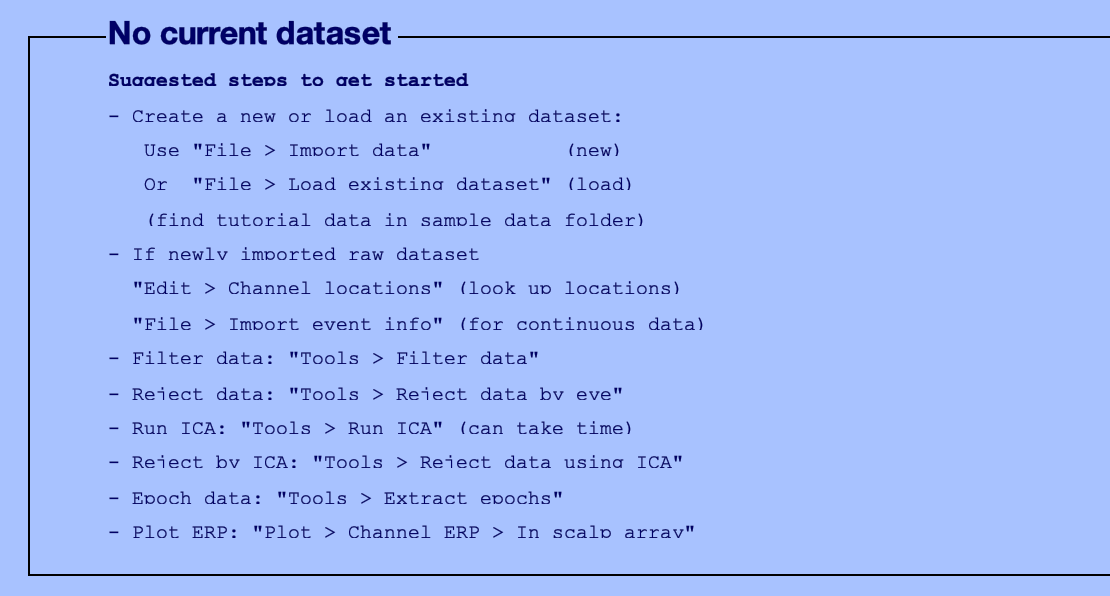

[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

EEG = pop_snapread(eeg.raw.path, 200.000000); %change relative gains here where it says 200


  Opened file /Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/EEG Data/B125/Raw/B125_8M.SMA for reading...
  Number of channels:    19
  Number of data points: 393153
  Sampling rate:         511.9 Hz

  Read 393153 frames, each one sync channel(1) and 18 data channels.
  Finding event transitions (>2.3) on channel 1 ...
  Total of 21 events found.
  Event channel 1 removed from output.

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: creating the original event table (EEG.urevent)


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'setname','B125_8M.raw',...
                                     'savenew',fullfile(eeg.processed.path, 'B125_8M.raw.set'),'gui','off'); 

Saving dataset...
Creating a new ALLEEG dataset 1


EEG.srate = 512;
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Read in channel locations for all except Cz, add Cz manually

%if site = wsu run the 19 chans, if vt run 26, if fau run 32
if strcmpi(site, 'WSU')

    % WSU channel locations
    EEG = pop_chanedit(EEG, 'load',{chans19,'filetype','autodetect'});
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
    EEG=pop_chanedit(EEG, 'insert',18,'changefield',{18,'labels','Cz'},'changefield',{18,'theta','90'},'changefield',{18,'radius','0'},'changefield',{18,'X','3.75e-33'},'changefield',{18,'Y','-6.12e-17'},'changefield',{18,'Z','1'},'changefield',{18,'sph_theta','-90'},'changefield',{18,'sph_phi','90'},'changefield',{18,'sph_radius','1'},'changefield',{18,'type','EEG'});
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

elseif strcmpi(site, 'VT')

    % VT channel locations
   EEG = pop_chanedit(EEG, 'load',{chans26,'filetype','autodetect'});
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
    EEG=pop_chanedit(EEG, 'insert',33,'changefield',{33,'labels','Cz'},'changefield',{33,'theta','90'}, ...
        'changefield',{33,'radius','0'},'changefield',{33,'X','3.75e-33'},'changefield',{33,'Y','-6.12e-17'}, ...
        'changefield',{33,'Z','1'},'changefield',{33,'sph_theta','-90'},'changefield',{33,'sph_phi','90'}, ...
        'changefield',{33,'sph_radius','1'},'changefield',{33,'type','EEG'});
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

elseif strcmpi(site, 'FAU')

    % FAU channel locations
    EEG = pop_chanedit(EEG, 'load',{chans32,'filetype','autodetect'});
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
    EEG=pop_chanedit(EEG, 'insert',33,'changefield',{33,'labels','Cz'},'changefield',{33,'theta','90'}, ...
        'changefield',{33,'radius','0'},'changefield',{33,'X','3.75e-33'},'changefield',{33,'Y','-6.12e-17'}, ...
        'changefield',{33,'Z','1'},'changefield',{33,'sph_theta','-90'},'changefield',{33,'sph_phi','90'}, ...
        'changefield',{33,'sph_radius','1'},'changefield',{33,'type','EEG'});
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

else

    error('Unrecognized site: %s. Please enter WSU, VT, or FAU.', site);

end

readlocs(): 'loc' format assumed from file extension



% Set all electrodes to type EEG
for i = 1:length(EEG.chanlocs)
    EEG.chanlocs(i).type = 'EEG';
end

%set ref as Cz
EEG=pop_chanedit(EEG, 'setref',{'1:19','Cz'});
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
EEG = pop_saveset( EEG, 'filename','B125_8M.czref.set','filepath',eeg.processed.path);

Saving dataset...


[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

Read in the .txt event file

EEG = pop_importevent( EEG, 'append','no','event',event.text.path,'fields',{'latency','type'},'skipline',1,'timeunit',1,'optimalign','off');

Reading file (lines): 10 20 26
eeg_checkset note: creating the original event table (EEG.urevent)


[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
EEG = pop_saveset( EEG, 'filename','B125_8M.events.set','filepath',eeg.processed.path);

Saving dataset...



[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);


Select only the multisite channels

[ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );

Creating a new ALLEEG dataset 2


EEG = pop_select( EEG, 'channel',{'FP1','FP2','F7','F3','F4','F8','T7','C3','C4','T8','P7','P3','P4','P8','O1','O2'});

Removing 2 channel(s)...


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1, ...
    'setname','B125_8M.multi','savenew',fullfile(eeg.processed.path, 'B125_8M.multi.set'), 'gui','off'); 

Saving dataset...
Creating a new ALLEEG dataset 3


Make sub-datasets per task

%% Read event file
event_file = event.text.path;

% Read tab-delimited file with headers
events = readtable(event_file, 'Delimiter', '\t');

% Output folder
save_path1 = eeg.processed.path;
save_path2 = eeg.happe.folder.path;

% Define start/end event pairs
segments = {
    'video_start',           'video_end';
    'm1_start',              'm1_end';
    'm2_start',              'm2_end';
    'm3_start',              'm3_end';
    'm4_start',              'm4_end';
    'mask_recovery_start',   'mask_recovery_end';
    'spider_start',          'spider_end';
    'spider_recovery_start', 'spider_recovery_end';
    'sa_enter_start',        'sa_enter_end';
    'sa_halfway_start',      'sa_halfway_end';
    'sa_half_start',         'sa_half_end';
    'sa_front_start',        'sa_front_end';
    'sa_pickup_start',       'sa_pickup_end';
    'sa_recovery_start',     'sa_recovery_end';
};

for i = 1:size(segments,1)

    start_type = segments{i,1};
    end_type   = segments{i,2};

    % Find the events
    start_row = find(strcmp(events.type, start_type), 1, 'first');
    end_row   = find(strcmp(events.type, end_type), 1, 'first');

    % Skip if either event is missing
    if isempty(start_row)
        warning('Start event "%s" not found. Skipping.', start_type);
        continue;
    end

    if isempty(end_row)
        warning('End event "%s" not found. Skipping.', end_type);
        continue;
    end

    % Convert event latencies to seconds
    start_time = events.latency(start_row);
    end_time   = events.latency(end_row);

    % Check that end comes after start
    if end_time <= start_time
        warning('End event "%s" occurs before start event "%s". Skipping.', ...
            end_type, start_type);
        continue;
    end

    % Extract EEG segment
    EEG_subset = pop_select(EEG, 'time', [start_time end_time]);

    % Remove "_start" from the event name for the filename
    segment_name = erase(start_type, '_start');

    % Name dataset
    EEG_subset.setname = sprintf('%s_%s', subjectID, segment_name);

    % Create filename
    filename = sprintf('%s_%s.set', subjectID, segment_name);

    % Save dataset
    EEG_subset = pop_saveset(EEG_subset, ...
        'filename', filename, ...
        'filepath', save_path1);

    EEG_subset = pop_saveset(EEG_subset, ...
        'filename', filename, ...
        'filepath', save_path2);

    fprintf('Saved %s\n', filename);

end

eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_video.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_m1.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_m2.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_m3.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_m4.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_mask_recovery.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_spider.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_spider_recovery.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_sa_enter.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_sa_half.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_sa_front.set


eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


Saving dataset...


Saved B125_8M_sa_pickup.set


Last step- check the preprocessed unsubsetted file

******************************************************
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.5 to the path
EEGLAB: adding "Cleanline" v2.1 (see >> help eegplugin_cleanline)


plugin_path = '/Users/kaitlyn_campbell/Desktop/HAPPE-master/Packages/eeglab2024.0/plugins/EEGLAB-specparam-master'

EEGLAB: adding "EEGLAB-specparam-master" v? (see >> help eegplugin_fooof)
 ** ERPLAB Studio now available! Launch by typing 'estudio' in the command window **
EEGLAB: adding "ERPLAB" v12.20 (see >> help eegplugin_erplab) - new version 13.10 available
EEGLAB: adding "FASTER" v1.2.4 (see >> help eegplugin_FASTER)
EEGLAB: adding "Fileio" v260210 to the path
EEGLAB: adding "ICLabel" v1.7 (see >> help eegplugin_iclabel)
EEGLAB: adding "MFFMatlabIO" v5.0 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "MST" v1.0 (see >> help eegplugin_microstate)
EEGLAB: adding "Mentalab" v0.2 (see >> help eegplugin_explore)
EEGLAB: adding "REST" v1.2 (see >> help eegplugin_rest)
EEGLAB: adding "bva-io" v1.75 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.11 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.6 (see >> help eegplugin_dipfit)
EEGLAB: adding "egilegacy" v1.0 (see >> help eegplugin_egilegacy)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
EEGLAB:

[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

EEG = pop_loadset('filename','B125_8M.multi.set','filepath',eeg.processed.path);

pop_loadset(): loading file /Users/kaitlyn_campbell/Library/CloudStorage/OneDrive-BaylorUniversity/Baby Bear Study/EEG Data/B125/Processed/B125_8M.multi.set ...


[ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );

Creating a new ALLEEG dataset 1


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


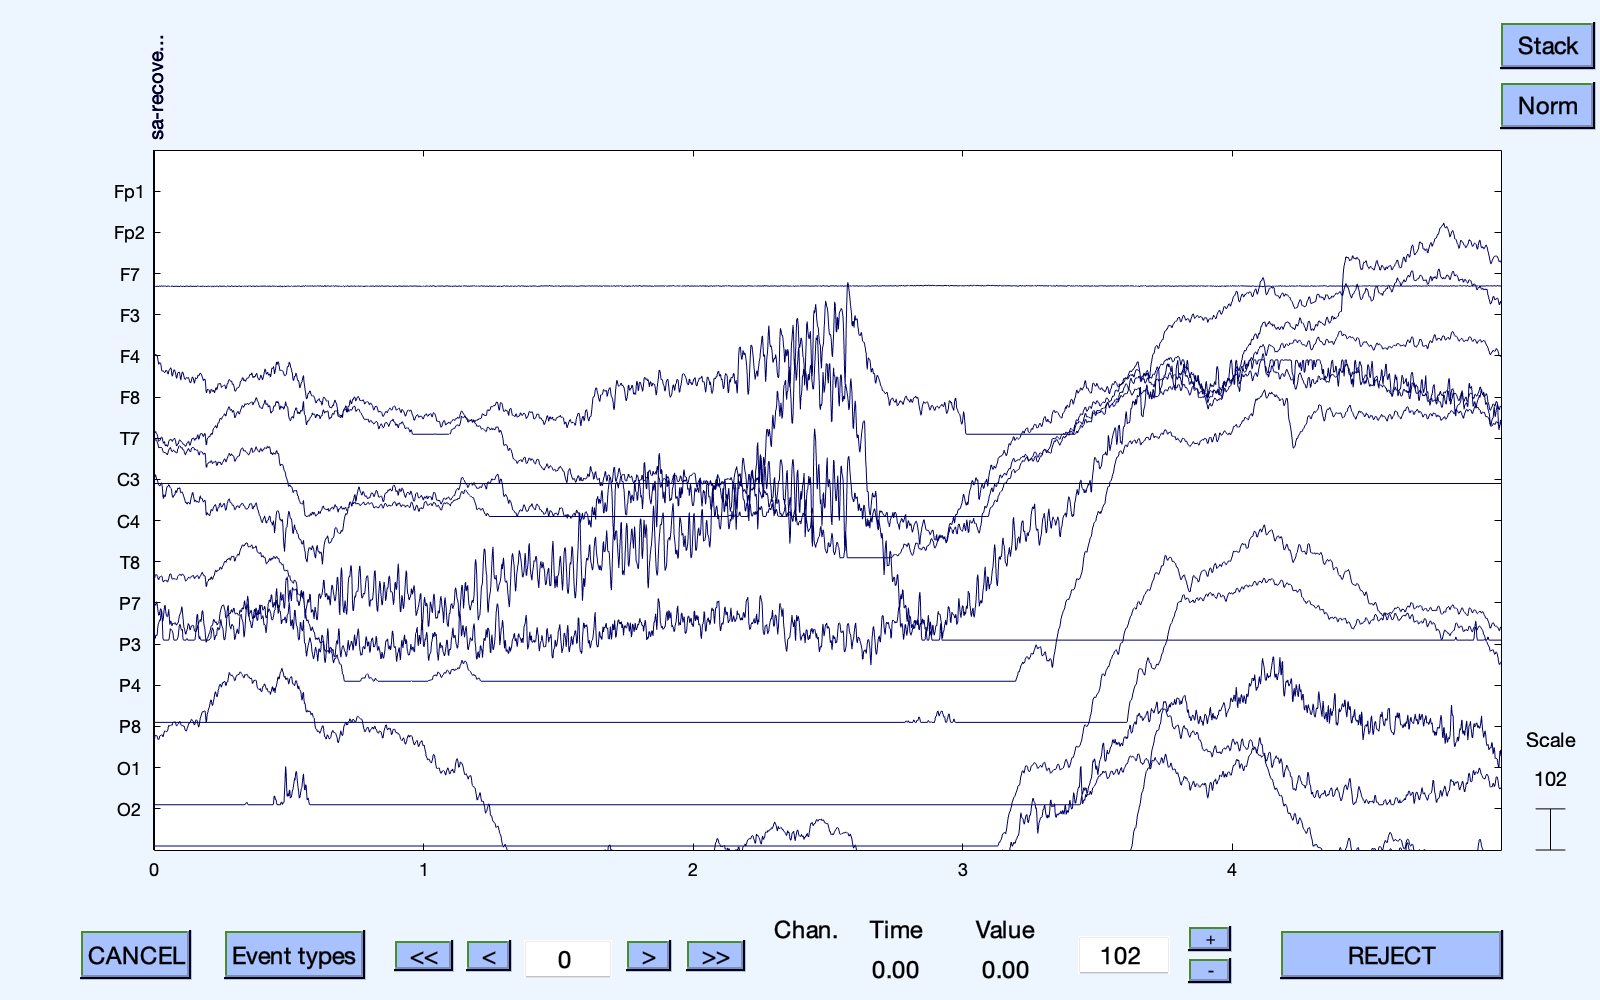

pop_eegplot( EEG, 1, 1, 1);

To check: 

- Make the new window full screeen

- Go to display > remove DC offset 

- Go to settings > time range to display > change to 10

- Go to the zoom (near the reject button on lower right) > change to 100

- Scroll through to your first event (video_start)

- Keep scrolling through and note any extra noisy electrodes, seemingly broken electrodes, or anything else a bit weird

- Note all these in your EEG preprocessing log